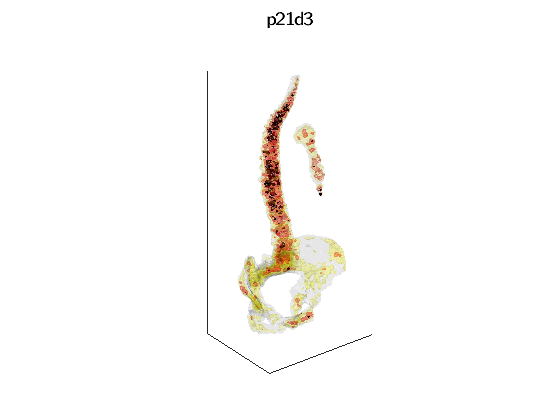

set(0,'DefaultTextFontname', 'LM Sans 12')
set(0,'DefaultAxesFontName', 'LM Sans 12')

preds_path = "C:\.matlab_workspace\.data\ct_mask_preds\";
ct_pt_path = "C:\.matlab_workspace\.data\ct_pt_volumes\";

figure();
pidx = [21,3];
mask_matfile = preds_path + "patient" + pidx(1) + "_day" + pidx(2) + "_pred.mat";
ct_pt_matfile = ct_pt_path + "patient" + pidx(1) + "_day" + pidx(2) + ".mat";
pt_scaled = scale_axialPET2CT(mask_matfile);
stern_mask_interp = interpolate_sternumMask2PET(ct_pt_matfile, mask_matfile);
stern_mask_interp = uint8(imbinarize(stern_mask_interp, 0.00001));
stern_mask_interp = extractLargestComponent3D(stern_mask_interp);
spine_mask_interp = interpolate_mask2PET(ct_pt_matfile, mask_matfile);
spine_mask_interp = uint8(imbinarize(spine_mask_interp, 0.00001));
spine_mask_interp = extractLargestComponent3D(spine_mask_interp);
pelvi_mask_interp = interpolate_pelvisMask2PET(ct_pt_matfile, mask_matfile);
pelvi_mask_interp = uint8(imbinarize(pelvi_mask_interp, 0.00001));
pelvi_mask_interp = extractLargestComponent3D(pelvi_mask_interp);
mask_interp = stern_mask_interp+pelvi_mask_interp+spine_mask_interp;
pt_masked = double(mask_interp) .* pt_scaled;
pt_masked_nan = pt_masked;
pt_masked_nan(pt_masked_nan == 0) = NaN;
[pt_hist_counts, pt_hist_edges] = histcounts(pt_masked_nan);
pt_cdf = cdfFromHist(pt_hist_counts);
cdf_idx_1 = getClosestValueIdx(pt_cdf, 0.50);
iso_val_1 = pt_hist_edges(cdf_idx_1);
cdf_idx_2 = getClosestValueIdx(pt_cdf, 0.85);
iso_val_2 = pt_hist_edges(cdf_idx_2);
cdf_idx_3 = getClosestValueIdx(pt_cdf, 0.98);
iso_val_3 = pt_hist_edges(cdf_idx_3);
fv0 = isosurface(pt_masked, 0.5);
fv1 = isosurface(pt_masked, iso_val_1);
fv2 = isosurface(pt_masked, iso_val_2);
fv3 = isosurface(pt_masked, iso_val_3);
p0 = patch(fv0,'FaceColor', 'black','EdgeColor','none');
p0.FaceAlpha = 0.05;
p1 = patch(fv1,'FaceColor', 'yellow','EdgeColor','none');
p1.FaceAlpha = 0.2;
p2 = patch(fv2,'FaceColor', 'red','EdgeColor','none');
p2.FaceAlpha = 0.3;
p2 = patch(fv3,'FaceColor', 'black','EdgeColor','none');
p2.FaceAlpha = 1;
xticks([]);
yticks([]);
zticks([]);
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-10)
lighting flat
title("\fontsize{14}p21d3");